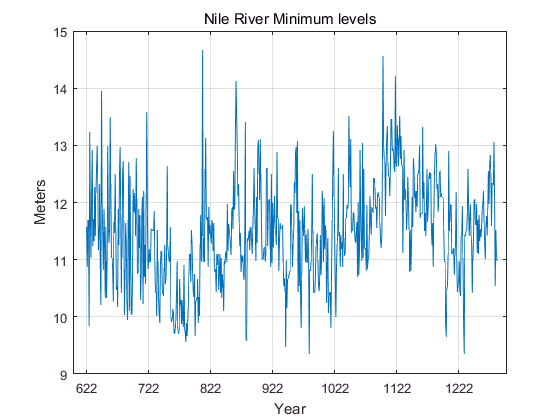

clear,close all,clc
load nileriverminima;
years = 622:1284;
figure;
plot(years,nileriverminima);
title('Nile River Minimum levels');
AX = gca;
AX.XTick = 622:100:1222;
grid on;
xlabel('Year');
ylabel('Meters');

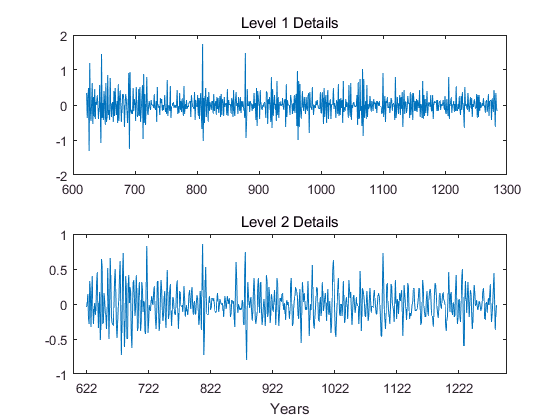

wt = modwt(nileriverminima,'haar',4);
mra = modwtmra(wt,'haar');
figure;
subplot(2,1,1)
plot(years,mra(1,:)); title('Level 1 Details');
subplot(2,1,2)
plot(years,mra(2,:)); title('Level 2 Details');
AX = gca;
AX.XTick = 622:100:1222;
xlabel('Years');

for JJ = 1:5
    pts_Opt = wvarchg(wt(JJ,:),2);
    changepoints{JJ} = pts_Opt;
end
cellfun(@(x) ~isempty(x),changepoints,'uni',0);
years(cell2mat(changepoints))

ans = 721

tspre = nileriverminima(1:100);
tspost = nileriverminima(101:end);
wpre = modwt(tspre,'haar',4);
wpost = modwt(tspost,'haar',4);
wvarpre = modwtvar(wpre,'haar',0.95,'table') % 0.95, Confidence intervals

wvarpre =           NJ     Lower      Variance     Upper 
          __    ________    ________    _______
    D1    99     0.25199     0.36053    0.55846
    D2    97     0.15367     0.25149    0.48477
    D3    93    0.056137     0.11014    0.30622
    D4    85    0.018881    0.047427    0.26453
    S4    85    0.017875      0.0449    0.25044

% NJ, number of nonboundary coefficients by scale.
% Lower, lower confidence bound for the variance estimate
% Variance, variance estimate by level
% Upper, upper confidence bound for the variance estimate
wvarpost = modwtvar(wpost,'haar',0.95,'table')

wvarpost =           NJ      Lower      Variance     Upper 
          ___    ________    ________    _______
    D1    562     0.11394     0.13354    0.15869
    D2    560    0.085288     0.10639    0.13648
    D3    556      0.0693    0.094168    0.13539
    D4    548    0.053644    0.081877    0.14024
    S4    548     0.24608     0.37558    0.64329

Vpre = table2array(wvarpre);
Vpost = table2array(wvarpost);
Vpre = Vpre(1:end-1,2:end)

Vpre =     0.2520    0.3605    0.5585
    0.1537    0.2515    0.4848
    0.0561    0.1101    0.3062
    0.0189    0.0474    0.2645

Vpost = Vpost(1:end-1,2:end)

Vpost =     0.1139    0.1335    0.1587
    0.0853    0.1064    0.1365
    0.0693    0.0942    0.1354
    0.0536    0.0819    0.1402

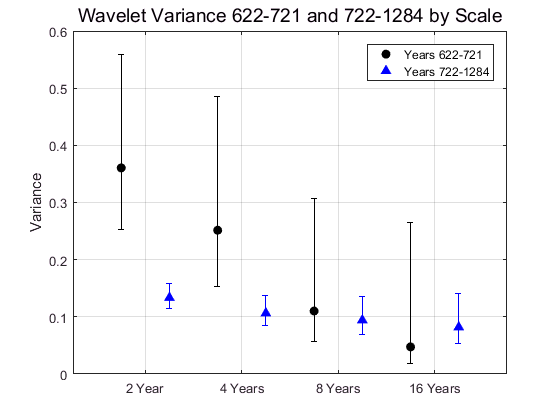


Vpre(:,1) = Vpre(:,2)-Vpre(:,1);
Vpre(:,3) = Vpre(:,3)-Vpre(:,2);

Vpost(:,1) = Vpost(:,2)-Vpost(:,1);
Vpost(:,3) = Vpost(:,3)-Vpost(:,2);

figure;
errorbar(1:4,Vpre(:,2),Vpre(:,1),Vpre(:,3),'ko','markerfacecolor',[0 0 0]);
hold on;
errorbar(1.5:4.5,Vpost(:,2),Vpost(:,1),Vpost(:,3),'b^','markerfacecolor',[0 0 1]);
set(gca,'xtick',1.25:4.25);
set(gca,'xticklabel',{'2 Year','4 Years', '8 Years', '16 Years','32 Years'});
grid on;
ylabel('Variance');
title('Wavelet Variance 622-721 and 722-1284 by Scale','fontsize',14);
legend('Years 622-721','Years 722-1284','Location','NorthEast');

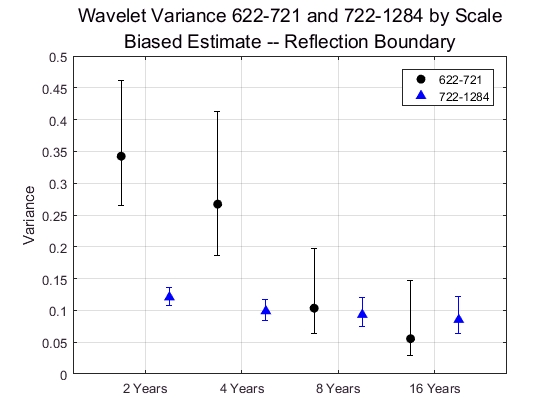

wpre = modwt(tspre,4,'reflection');
wpost = modwt(tspost,4,'reflection');
wvarpre = modwtvar(wpre,[],[],'EstimatorType','biased','Boundary','reflection','table');
wvarpost = modwtvar(wpost,[],[],'EstimatorType','biased','Boundary','reflection','table');
Vpre = table2array(wvarpre);
Vpost = table2array(wvarpost);
Vpre = Vpre(1:end-1,2:end);
Vpost = Vpost(1:end-1,2:end);

Vpre(:,1) = Vpre(:,2)-Vpre(:,1);
Vpre(:,3) = Vpre(:,3)-Vpre(:,2);

Vpost(:,1) = Vpost(:,2)-Vpost(:,1);
Vpost(:,3) = Vpost(:,3)-Vpost(:,2);

figure;
errorbar(1:4,Vpre(:,2),Vpre(:,1),Vpre(:,3),'ko','markerfacecolor',[0 0 0]);
hold on;
errorbar(1.5:4.5,Vpost(:,2),Vpost(:,1),Vpost(:,3),'b^','markerfacecolor',[0 0 1]);
set(gca,'xtick',1.25:4.25);
set(gca,'xticklabel',{'2 Years','4 Years', '8 Years', '16 Years','32 Years'});
% 如何确定这个横坐标的信息？
% 其实依赖的Wavelet分解的不同level，
% 从结果来看，第一层认为是2 Year，第二层是4 Year， 后面以此类推
% 这个类推的过程倒是符合Wavelet Transformation的尺度变换，但是如何确定level 1表示2 Year呢？
% 这个重要的关系是如何确定的？
grid on;
ylabel('Variance');
title({'Wavelet Variance 622-721 and 722-1284 by Scale'; ...
    'Biased Estimate -- Reflection Boundary'},'fontsize',14);
legend('622-721','722-1284','Location','NorthEast');
hold off;

The conclusion is reinforced.

There is significant difference in the variance of the data over **scales **of 2 and 4 years, but not at **longer scales.**

You can conclude that something has changed about the process variance.

主要的用途：应该是用于找到最佳的时间尺度对元数据进行分析与理解。

Using the wavelet transform allows you to focus on **scales **where the change is volatility is localized. 

**启发**：能否在找到最佳的scales的基础上对moving windows algorithms提供更多的信息以进行更好的窗口长度与滑动窗进行参数设计